# Tuning a PI compensator

This livescript is a brief manual in support of the app ***pi_tuning.mlapp***.   This is a simple interface to practice the role of PI compensation for a range of different systems.    The exemplar systems are chosen carefully so that a limited range of compensator values are adequate and can be captured with a slider range of 0 to 4.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, University of Sheffield   and Ioannis Myrsinias (Mathworks)                      

## Table of contents

- Closed-loop context

- Closed-loop transfer functions

- Closed-loop responses

- PI tuning

- Interface and user interaction

## 1. Control loop context

Consider a system with a loop diagram given as follows, where *Y(s), U(s), R(s), D(s)* respresent the output, input, target and disturbance respectively. The transfer function $C\left(s\right)=\left(K_p +\frac{K_i }{s}\right)$is the PI compensator and *G(s)* represents the system model.

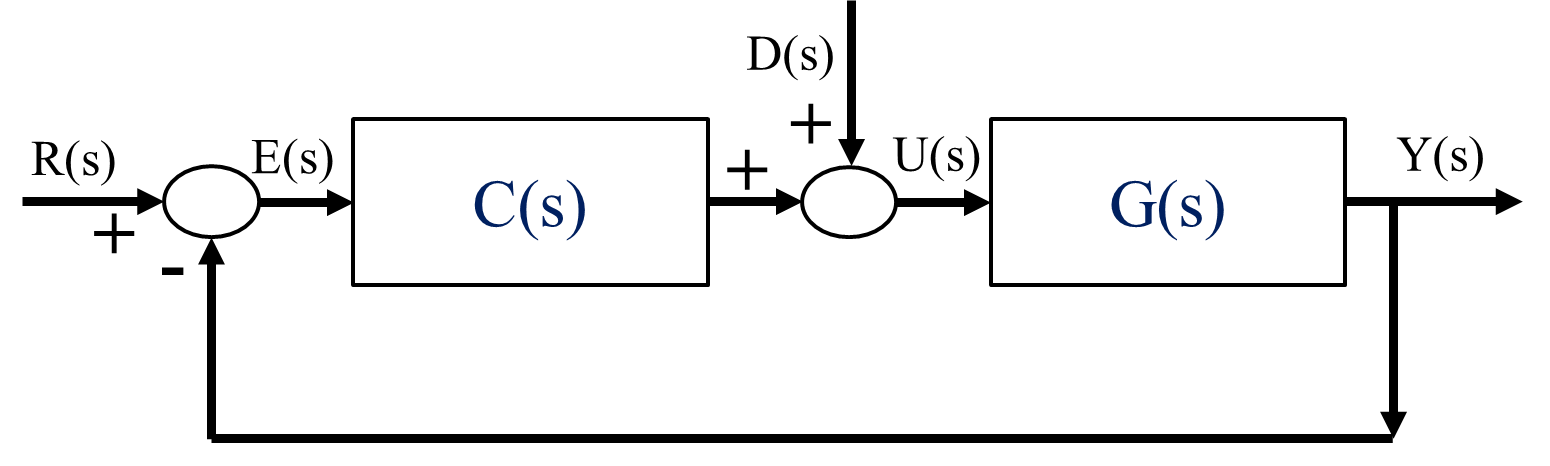

## 2. Closed-loop transfer functions

Using a standard feedback loop derivations we have:

$Y_r \left(s\right)=G_c \left(s\right)R\left(s\right)$ with   $G_c =\frac{\textrm{GC}}{1+\textrm{GC}}$         Dependence of output on the target.

$U_r \left(s\right)=G_{\textrm{cu}} \left(s\right)R\left(s\right)$ with   $G_{\textrm{cu}} =\frac{C}{1+\textrm{GC}}$    Dependence of input on the target.

$Y_d \left(s\right)=G_{\textrm{cd}} \left(s\right)D\left(s\right)$ with   $G_{\textrm{cd}} =\frac{G}{1+\textrm{GC}}$    Dependence of output on the disturbance.

$U_d \left(s\right)=G_{\textrm{cud}} \left(s\right)D\left(s\right)$ with   $G_{\textrm{cud}} =\frac{1}{1+\textrm{GC}}$    Dependence of input on the disturbance.

% Code to create closed-loop transfer functions
G=tf(4,[1 2])

G =
 
    4
  -----
  s + 2
 
Continuous-time transfer function.



C =
 
  0.5 s + 2
  ---------
      s
 
Continuous-time transfer function.



Gc =
 
     2 s + 8
  -------------
  s^2 + 4 s + 8
 
Continuous-time transfer function.



Gcu =
 
  0.5 s^2 + 3 s + 4
  -----------------
    s^2 + 4 s + 8
 
Continuous-time transfer function.



Gcd =
 
       4 s
  -------------
  s^2 + 4 s + 8
 
Continuous-time transfer function.



Gcud =
 
    s^2 + 2 s
  -------------
  s^2 + 4 s + 8
 
Continuous-time transfer function.



Kp=0.5; Ki=2;
C=tf([Kp,Ki],[1 0])
Gc=feedback(G*C,1)
Gcu=feedback(C,G)
Gcd = feedback(G,C)
Gcud=feedback(1,G*C)

## 3. Closed-loop responses

We can build the responses by choosing values for *G,C,D (R=1* for simplicity) and then using standard Matlab commands.

The total output and input are given as:


$$Y=Y_r +Y_d ;\;\;\;\;\;\;\;\;\;\;\;U=U_r +U_d$$


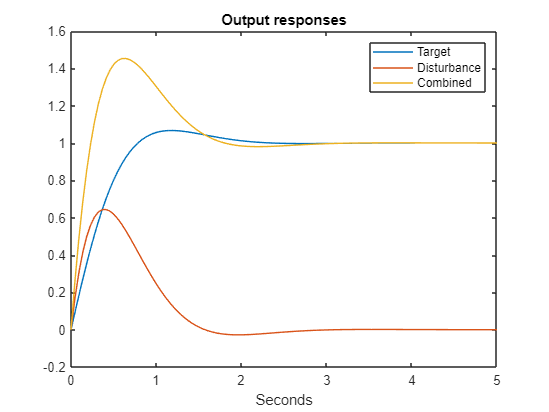

disp('********************************************************')
disp('Section 3 below')

% collect responses
endtime=5;
[y1,t]=step(Gc,endtime);
u1 = step(Gcu,t);
y2 = step(Gcd,t);

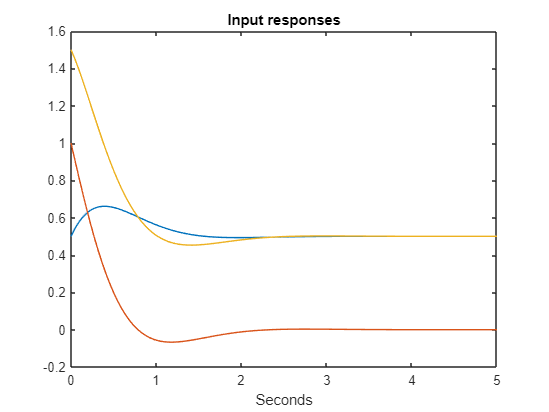

u2 = step(Gcud,t);

% Plot responses

plot(t,y1,t,y2,t,y1+y2);
legend('Target','Disturbance','Combined');
title('Output responses')
xlabel('Seconds')
plot(t,u1,t,u2,t,u1+u2);
title('Input responses')
xlabel('Seconds')

## 4. PI Tuning

The main aim of the app is to allow a student to practice tuning of PI compensators for a variety of system models. No specific guidance is given on how to tune (see line 2 of the code above for *Kp, Ki *choices used here), rather this is an environment which allows easy visualisation of the impact of parameter changes on behaviour.

- The PI parameters are chosen through sliders.

- The model parameters can be taken from a short default list, or the user can enter the numerator and denominator coefficients directly.

- The corresponding closed-loop behaviour and poles are plotted once the users selects the "simulate" button.

- Plots of behaviour and overlaid with previous plots so that users can keep track of the impact of any changes they have made, as is clear in the image at the end of this file. The figures can be refreshed to being a new set of investigations using the "refresh" button.

## 5. Interface and user interaction

The user can change only a few parameters as we want to keep the app simple and transparent to use.

- The *Kp* and *Ki* parameters can be selected from the sliders; only a limited range is allowed but users can easily modify this by changing the source code. ***[Due to the slider limits, it is advised that users restrict model choices to open-loop gains in the range of around 1 and dominant time constants also in the range of around 1 sec.]***

- The system model can be taken from: i) a limited selection of "example" models or ii) using the "custom" tab to enter the numerator and denominator coefficients (using Matlab notation) and then selecting the "load" button. 

- The disturbance is selected from a slider; again only a limited range is coded.

- The closed-loop step responses (input and output) are plotted and overlaid with earlier results for ease of comparison.  Closed-loop poles are also displayed at the bottom for the current choices only.

Users can run the simulation with various choices of parameters and overlay the results so they can build a picture and understanding of the impact of different changes. To refresh and begin again, use the clear button.

The animation on/off button allows the user to get instant updates rather than having the lines animated.